# **demo03 of Im2mesh package**

demo03 - How to export mesh as inp and bdf file

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Circle

Let's start demo. First, we'll use function im2mesh to generate mesh. In the next step, we'll export the mesh.

Import image Circle.tif.

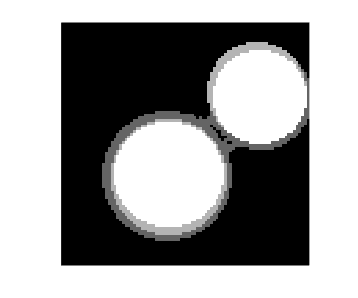

im = imread("Circle.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

opt = [];       % reset opt
opt.tf_avoid_sharp_corner = true;
opt.threshold_num_turning = 10;
opt.threshold_num_vert_Smo = 20;
opt.threshold_num_vert_Sim = 20;

[ vert, tria, tnum, vert2, tria2 ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                352                444
         10                383                806
         13                384                887


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                502                444
         10                522               1685
         20                529               2541
         23                530               2556


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                549               2534
     

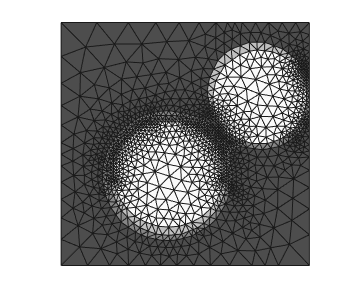

plotMeshes( vert, tria, tnum )

## Prepare for mesh export

Setup parameters.

% parameters for mesh export
dx = 1; dy = 1;     % scale of your imgage
                    % dx - column direction, dy - row direction
                    % e.g. scale of your imgage is 0.11 mm/pixel, try
                    %      dx = 0.11; and dy = 0.11;
                    
precision_nodecoor = 8; % precision of node coordinates, for printInp
                        % e.g. precision_nodecoor=4, dx=1 -> 0.5000 
                        %      precision_nodecoor=3, dx=0.111, -> 0.055

Scale node coordinates according to dx and dy.

% scale node coordinates of linear elements
vert( :, 1 ) = vert( :, 1 ) * dx;
vert( :, 2 ) = vert( :, 2 ) * dy;

% scale node coordinates of quadratic elements
vert2( :, 1 ) = vert2( :, 1 ) * dx;
vert2( :, 2 ) = vert2( :, 2 ) * dy;

## Reorgnize nodes and elements

We use function getNodeEle to reorganize node coordinates and elements from the mesh, and add node numbering and element numbering.

% for linear element
[ nodecoor_list, nodecoor_cell, ele_cell ] = getNodeEle( vert, tria, tnum );

[ nodecoor_list, nodecoor_cell, ele_cell ] is an alternative way to represent the triangular mesh. The format is convenient for importing the mesh into commercial finite element software. The meaning of these three variable is listed as follows. We will write these three variables nodecoor_list, nodecoor_cell, ele_cell to inp file and bdf file later.

nodecoor_list is node coordinates, N-by-3 array.

nodecoor_cell is a 1-by-P cell array. nodecoor_cell{i} represents the node numbering and node coordinates in the i-th phase.

ele_cell is a 1-by-P cell array. ele_cell{i} represent elements in the i-th phase.

We can do the same operation to quadratic elements using the same function.

% for quadratic element
[ nodecoor_list_Q, nodecoor_cell_Q, ele_cell_Q ] = getNodeEle( vert2, tria2, tnum );

## Export mesh as bdf file (Nastran bulk data)

We use function printBdf to do that. The bdf file 'test.bdf' will be saved to current folder.

printBdf( nodecoor_list, ele_cell, precision_nodecoor );

printBdf Done! Check the bdf file!


We can explictly specify the file name.

file_name = 'test_2025.bdf';
printBdf( nodecoor_list, ele_cell, precision_nodecoor, file_name );

printBdf Done! Check the bdf file!


## Export mesh as inp file (Abaqus)

Here, we use function printInp_multiSect to save multiple phases in the mesh as multiple sections. 

The exported inp file would have a model with one part, which contains multiple sections. Each section corresponds to one phase in your image.

### Linear element

Before exporting mesh, we specify element type.

ele_type = 'CPS3';  % element type, for printInp

We use function printInp_multiSect to save multiple phases in the mesh as multiple sections. The inp file will be saved to current folder.

% print as multiple sections
file_name = 'test_linear.inp';
printInp_multiSect( nodecoor_list, ele_cell, ele_type, precision_nodecoor, file_name );

printInp_multiSect Done! Check the inp file!


### Quadratic element

We can do the same operation to quadratic elements. 

ele_type_Q = 'CPS6';  % element type, for printInp

To avoid confusion, you can explictly specify the file name.

% print as multiple sections
file_name = 'test_quadratic.inp';
printInp_multiSect( nodecoor_list_Q, ele_cell_Q, ele_type_Q, precision_nodecoor, file_name );

printInp_multiSect Done! Check the inp file!


## Other comments

Multiple phases in the mesh can also be saved as multiple parts. We use function printInp_multiPart.

The exported inp file would has a model with multiple parts, where each part corresponds to one phase in the image.

Caution: function printInp_multiPart (written by me in 2018) maybe outdated. It may has bug when doing simulation in Abaqus.

Im2mesh can also export mesh as .node/.ele file, but I didn't test the following function.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo